# Questão 5

## Para os dados 3

clear;
fileID = fopen('dados_3.txt', 'r');
formatSpec = '\t%f\t%f';
sizeData = [2 Inf];
dados_3 = fscanf(fileID, formatSpec, sizeData);
dados_3 = transpose(dados_3);

Aplicando o algoritmo de mínimos quadrados recursivos com um fator de esquecimento $\lambda =0\ldotp 95$

y_3 = dados_3(:, 1);
u_3 = dados_3(:, 2);
lambda = .95;

Estimação usando modelo ARX

% Modelo ARX de ordem 1
[theta1, estimative1] = RLS(1, lambda, y_3, u_3);
error1 = y_3 - estimative1;

% Modelo ARX de ordem 2
[theta2, estimative2] = RLS(2, lambda, y_3, u_3);
error2 = y_3 - estimative2;

% Modelo ARX de ordem 3
[theta3, estimative3] = RLS(3, lambda, y_3, u_3);
error3 = y_3 - estimative3;

% Modelo ARX de ordem 4
[theta4, estimative4] = RLS(4, lambda, y_3, u_3);
error4 = y_3 - estimative4;

% Modelo ARX de ordem 5
[theta5, estimative5] = RLS(5, lambda, y_3, u_3);
error5 = y_3 - estimative5;

Estimação usando modelo ARMAX

% Modelo ARMAX de ordem 1
[theta1x, estimative1x] = RLS(1, lambda, y_3, u_3, error1);
error1x = y_3 - estimative1x;

% Modelo ARMAX de ordem 2
[theta2x, estimative2x] = RLS(2, lambda, y_3, u_3, error2);
error2x = y_3 - estimative2x;

% Modelo ARMAX de ordem 3
[theta3x, estimative3x] = RLS(3, lambda, y_3, u_3, error3);
error3x = y_3 - estimative3x;

% Modelo ARMAX de ordem 4
[theta4x, estimative4x] = RLS(4, lambda, y_3, u_3, error4);
error4x = y_3 - estimative4x;

% Modelo ARMAX de ordem 5
[theta5x, estimative5x] = RLS(5, lambda, y_3, u_3, error5);
error5x = y_3 - estimative5x;

Validação

epsilon = length(y_3)/2;
[estimative1v, error1v] = rvalidate(theta1, epsilon, y_3, u_3);
[estimative2v, error2v] = rvalidate(theta2, epsilon, y_3, u_3);
[estimative3v, error3v] = rvalidate(theta3, epsilon, y_3, u_3);
[estimative4v, error4v] = rvalidate(theta4, epsilon, y_3, u_3);
[estimative5v, error5v] = rvalidate(theta5, epsilon, y_3, u_3);

Comparativo erros de estimação

error = [mean(error1.^2), mean(error1v.^2), mean(error1x.^2)];
error = [error; mean(error2.^2), mean(error2v.^2), mean(error2x.^2)];
error = [error; mean(error3.^2), mean(error3v.^2), mean(error3x.^2)];
error = [error; mean(error4.^2), mean(error4v.^2), mean(error4x.^2)];
error = [error; mean(error5.^2), mean(error5v.^2), mean(error5x.^2)];
error

error =     0.0476    0.0731    0.0416
    0.0404    0.0579    0.0389
    0.0428    0.0589    0.0418
    0.0441    0.0604    0.0434
    0.0454    0.0613    0.0449


Seguindo o raciocínio da questão anterior, o modelo escolhido foi o modelo 2

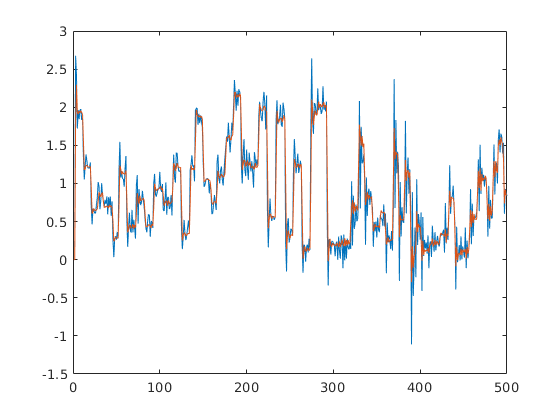

plot(y_3);
hold on;
plot(estimative2x);
hold off;

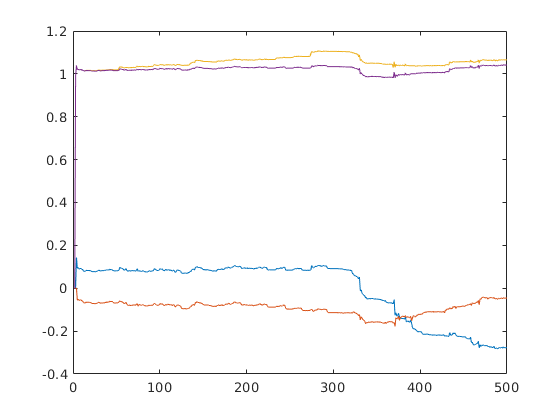

plot(theta2(:,1));
hold on;
plot(theta2(:,2));
plot(theta2(:,3));
plot(theta2(:,4));
hold off;

## Para os dados 4

clear;
fileID = fopen('dados_4.txt', 'r');
formatSpec = '\t%f\t%f';
sizeData = [2 Inf];
dados_4 = fscanf(fileID, formatSpec, sizeData);
dados_4 = transpose(dados_4);

Aplicando o algoritmo de mínimos quadrados recursivos com um fator de esquecimento $\lambda =0\ldotp 99$

y_4 = dados_4(:, 1);
u_4 = dados_4(:, 2);
lambda = .99;

Estimação usando modelo ARX

% Modelo ARX de ordem 1
[theta1, estimative1] = RLS(1, lambda, y_4, u_4);
error1 = y_4 - estimative1;

% Modelo ARX de ordem 2
[theta2, estimative2] = RLS(2, lambda, y_4, u_4);
error2 = y_4 - estimative2;

% Modelo ARX de ordem 3
[theta3, estimative3] = RLS(3, lambda, y_4, u_4);
error3 = y_4 - estimative3;

% Modelo ARX de ordem 4
[theta4, estimative4] = RLS(4, lambda, y_4, u_4);
error4 = y_4 - estimative4;

% Modelo ARX de ordem 5
[theta5, estimative5] = RLS(5, lambda, y_4, u_4);
error5 = y_4 - estimative5;

Estimação usando modelo ARMAX

% Modelo ARMAX de ordem 1
[theta1x, estimative1x] = RLS(1, lambda, y_4, u_4, error1);
error1x = y_4 - estimative1x;

% Modelo ARMAX de ordem 2
[theta2x, estimative2x] = RLS(2, lambda, y_4, u_4, error2);
error2x = y_4 - estimative2x;

% Modelo ARMAX de ordem 3
[theta3x, estimative3x] = RLS(3, lambda, y_4, u_4, error3);
error3x = y_4 - estimative3x;

% Modelo ARMAX de ordem 4
[theta4x, estimative4x] = RLS(4, lambda, y_4, u_4, error4);
error4x = y_4 - estimative4x;

% Modelo ARMAX de ordem 5
[theta5x, estimative5x] = RLS(5, lambda, y_4, u_4, error5);
error5x = y_4 - estimative5x;

Validação

epsilon = length(y_4)/2;
[estimative1v, error1v] = rvalidate(theta1, epsilon, y_4, u_4);
[estimative2v, error2v] = rvalidate(theta2, epsilon, y_4, u_4);
[estimative3v, error3v] = rvalidate(theta3, epsilon, y_4, u_4);
[estimative4v, error4v] = rvalidate(theta4, epsilon, y_4, u_4);
[estimative5v, error5v] = rvalidate(theta5, epsilon, y_4, u_4);

Comparativo erros de estimação

error = [mean(error1.^2), mean(error1v.^2), mean(error1x.^2)];
error = [error; mean(error2.^2), mean(error2v.^2), mean(error2x.^2)];
error = [error; mean(error3.^2), mean(error3v.^2), mean(error3x.^2)];
error = [error; mean(error4.^2), mean(error4v.^2), mean(error4x.^2)];
error = [error; mean(error5.^2), mean(error5v.^2), mean(error5x.^2)];
error

error =     0.2053    0.1963    0.1699
    0.0993    0.1093    0.0932
    0.1004    0.1070    0.0965
    0.1034    0.1102    0.1008
    0.1055    0.1127    0.1033


Seguindo o raciocínio da questão anterior, o modelo escolhido foi o modelo 2

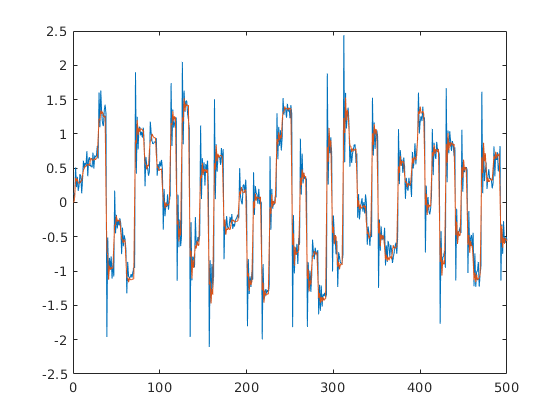

plot(y_4);
hold on;
plot(estimative2x);
hold off;

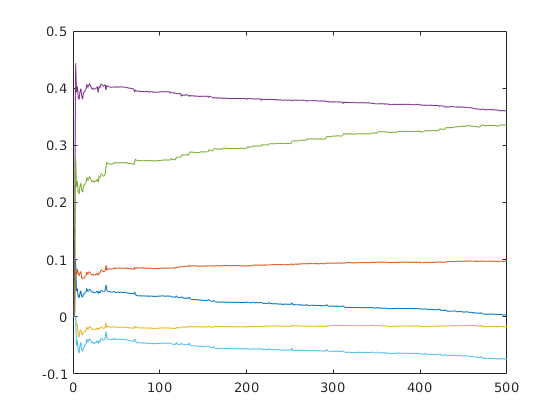

plot(theta3(:,1));
hold on;
plot(theta3(:,2));
plot(theta3(:,3));
plot(theta3(:,4));
plot(theta3(:,5));
plot(theta3(:,6));
hold off;